## Exercise 3

- Please submit answers as code and/or text inside this live notebook

- Code answers will be assessed on both correctness and design.

- You are welcome to work together but all answers should reflect your own understanding and communication.

- NB: You may consider using [https://matlab.mathworks.com/](https://matlab.mathworks.com/) if your laptop struggles with large datasets.

- NB: Avoid unnecessarily duplicating code in answers to individual questions.

#### 1. Using pre-defined parcellations

For this exercise, we will use pre-defined parcellations based on correlation structure, as defined by [Schaefer et al. (2018)](https://academic.oup.com/cercor/article/28/9/3095/3978804). The data on Brightspace contains ten different granularities of this parcellations (from 100 to 1000 parcels) in volume and surface based formats.

% add toolboxes to path
addpath('/home/tonnar/Fall2021/Class/BME/Class/gifti-main');                  % add gifti toolbox to path
addpath('/home/tonnar/Fall2021/Class/BME/Class/cifti-matlab-master');         % add cifti toolbox to path
addpath('/home/tonnar/Fall2021/Class/BME/Class/cifti-matlab-master/ft_cifti');

**(1.1)** Visualize the ten parcellations on left and right hemisphere *inflated_MSMAll* surfaces. For each visualization, make a randomly generated colormap that assigns a unique color to each distinct parcel.

%surface files
surface_parcs = {};
files = dir(fullfile('/home/tonnar/Fall2021/Class/BME/Data/Surface_Data', "*.nii"));
for i = 2:size(files,1)
    surface_parcs{i-1} = ft_read_cifti(files(i).name);
end
surface_parcs{10} = ft_read_cifti(files(1).name);

%volume files
volume_parcs = {};
files = dir(fullfile('/home/tonnar/Fall2021/Class/BME/Data/Volume_Data', "*.gz"));
for i = 2:size(files,1)
    volume_parcs{i-1} = niftiread(files(i).name);
end
volume_parcs{10} = niftiread(files(1).name);

%inflated
gii_left = gifti('/home/tonnar/Fall2021/Class/BME/Data/Inflated/S1200.L.inflated_MSMAll.32k_fs_LR.surf.gii');
gii_right = gifti('/home/tonnar/Fall2021/Class/BME/Data/Inflated/S1200.R.inflated_MSMAll.32k_fs_LR.surf.gii');
h = size(gii_left.vertices, 1);

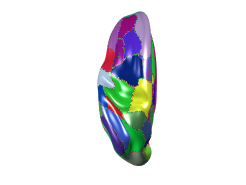

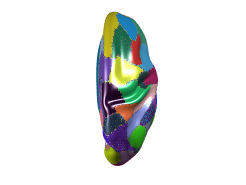

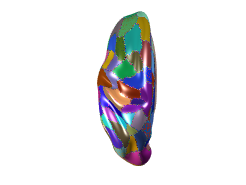

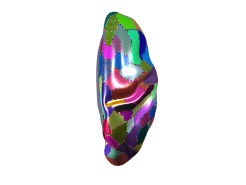

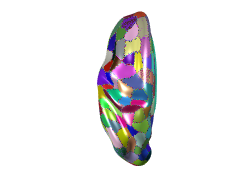

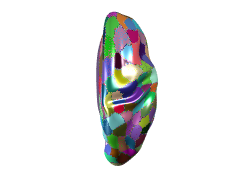

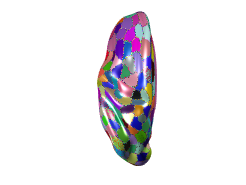

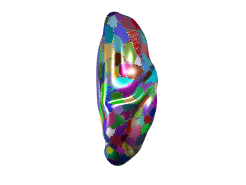

%parcellations on inflated
for i = 1:length(surface_parcs)
    surface_parc = surface_parcs{i};
    cii_left.cdata = surface_parc.parcels(1:h);
    cii_right.cdata = surface_parc.parcels(h+(1:h));
    
    figure;
    plot(gii_left, cii_left);
    colormap(rand(max(surface_parc.parcels),3))
    figure;
    plot(gii_right, cii_right);
    colormap(rand(max(surface_parc.parcels),3))
end

**(1.2) **Compute and store parcel timeseries for each of the 10 surface parcellations and separately for each of the 10 volume parcellations.

%surface parcs
surface_data = ft_read_cifti('rfMRI_REST1_LR_Atlas_MSMAll_hp2000_clean.dtseries.nii');
t = size(surface_data.dtseries, 2);
surface_parc_ts = {};

for i = 1:length(surface_parcs)
    surface_parc = surface_parcs{i};
    p = max(surface_parc.parcels);     
    X = zeros(p, t);       
    for j = 1:p
        X(j, :) = mean(surface_data.dtseries(find(surface_parc.parcels == j), :), 1, 'omitnan');
    end
    surface_parc_ts{i} = X;
end

%volume parcs
volume_data = niftiread('rfMRI_REST1_LR_hp2000_clean.nii.gz');
[x, y, z, t] = size(volume_data);
volume_parc_ts = {};
for i = 1:length(volume_parcs)   
    volume_parc = volume_parcs{i};
    p = max(volume_parc, [], 'all');  
    volume_data = reshape(volume_data, [], t);   
    volume_parc = reshape(volume_parc, [], 1); 
    X = zeros(p, t);
    for j = 1:p
        X(j, :) = mean(volume_data(volume_parc==j, :), 1);
    end
    volume_parc_ts{i} = X;
end

**(1.3)** For each of the 10 granularities, compute the Pearson correlation coefficients between the corresponding timeseries of individual surface and volume parcels.

%surface corr
corrs = {};
for i = 1:length(surface_parc_ts)
    X1 = normalize(surface_parc_ts{i}, 2);
    X2 = normalize(volume_parc_ts{i}, 2);
    corrs{i} = diag(corr(X1', X2'));
end

**(1.4) **Use the function `swarmchart` to visualize the Pearson correlation coefficients in the previous question as a function of parcel granularity. Describe and try to interpret your findings.

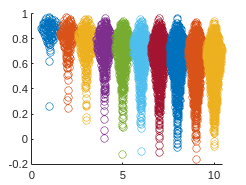

%swarmchat surface
figure;
hold on
for i = 1:length(corrs)
    x1 = ones(1,length(corrs{i})) * i;
    swarmchart(x1, corrs{i})
end
hold off

What we can see is that as the number of parcellations increases the amount smaller correlations rise. This makes seems to make sense because we would expect the smaller regions to have more specific values to them allowing for more variation and thus lower correlation. However, it is interesting that there does seem to appear to be any a very small amount of negative correlations.

**(1.5) **For each of the 10 granularities, visualize the Pearson correlation coefficients on left and right hemisphere *inflated_MSMAll* surfaces. Use the function `caxis` to enforce the same color bounds on all plots. Describe and try to interpret your findings (feel free to reach out and discuss these with me).

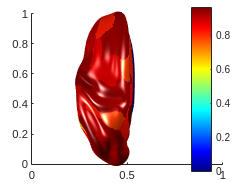

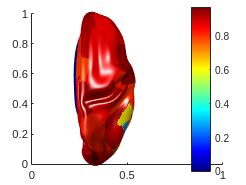

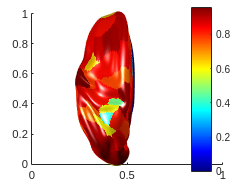

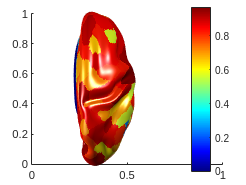

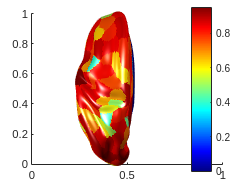

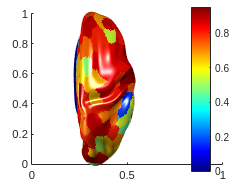

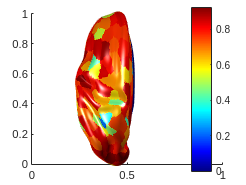

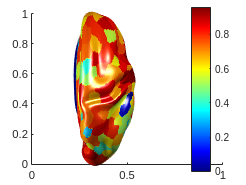

for i = 1:length(corrs)
    corr_df = corrs{i};
    parc = surface_parcs{i};
    holder = parc.parcels;
    for j = 1:length(parc.parcels)
        x = parc.parcels(j);
        if x == 0
        else    
           holder(j) = corr_df(x);
        end        
    end %add right as well.
    cii_left.cdata = holder(1:h);
    cii_right.cdata = holder(h+(1:h));
    figure;
    caxis([-1 1]);
    plot(gii_left, cii_left);
    colormap("jet");
    colorbar;
    figure;
    caxis([-1 1]);
    plot(gii_right, cii_right);
    colormap("jet");
    colorbar;
end

The main finding here is that for lower parcellations we see that the surface appears to be much more correlated. As I had mentioned above I would expect this because as we increase the number of brain regions we would expect the activity within each region to become more localized to a specific subarea which would have a different activation pattern in a volume vs surface level parcellation. 

#### 2. K-means clustering

**(2.1)** Add the kmeans code from class to the bottom of this live notebook, as a helper function. Name this function something other than "kmeans" to avoid confusion with MATLAB's built-in `kmeans` function.

Modify this function to additionally compute the average correlation between a node and its cluster centroid (i.e. the k-means objective $-\frac{1}{n}J=\frac{1}{n}\sum_{\mathit{\mathbf{u}}\in \mathit{\mathbf{K}}} \sum_{i\in \mathit{\mathbf{u}}} \textrm{corr}\left({\mathit{\mathbf{x}}}_i ,{\mathit{\mathbf{x}}}_u \right)$). Display the value of this quantity at each iteration, alongside "fractional change". Make the function to return this value for a converged partition, as well as the converged partition itself.

**(2.2)** For this exercise, we will use the *1000-parcel surface parcellation* timeseries computed in exercise 1. Make sure that the dimensions of these data are $1000\times 1200$. Run your kmeans helper function to compute clusterings of 20, 40, 60, 80, 100 clusters on these data. Run your kmeans function 100 times for each number of clusters (so that you will end up with 500 different clusterings in total).

clusters = {};
mean_correlations = {};
data = surface_parc_ts{1};
for i = 1:5
    cluster = [];
    mean_correlation = [];
    for j = 1:100
        [K, mean_corr] = myKmeans(data, 20 * i);
        cluster = [cluster, K];
        mean_correlation = [mean_correlation, mean_corr];
    end
    clusters{i} = cluster;
    mean_correlations{i} = mean_correlation;
end

fractional change: 0.41 | mean correlation: 0.60725
fractional change: 0.16 | mean correlation: 0.7044
fractional change: 0.04 | mean correlation: 0.73423
fractional change: 0 | mean correlation: 0.7396
fractional change: 0.41 | mean correlation: 0.62742
fractional change: 0.13 | mean correlation: 0.71203
fractional change: 0.05 | mean correlation: 0.73203
fractional change: 0.02 | mean correlation: 0.73684
fractional change: 0.01 | mean correlation: 0.73873
fractional change: 0 | mean correlation: 0.73919
fractional change: 0.35 | mean correlation: 0.59612
fractional change: 0.18 | mean correlation: 0.68124
fractional change: 0.09 | mean correlation: 0.71333
fractional change: 0.03 | mean correlation: 0.72731
fractional change: 0.01 | mean correlation: 0.73172
fractional change: 0.02 | mean correlation: 0.73256
fractional change: 0 | mean correlation: 0.73422
fractional change: 0.36 | mean correlation: 0.63452
fractional change: 0.11 | mean correlation: 0.70368
fractional change: 0.06

**(2.3)** Use the function `swarmchart` to visualize the average correlation between a node and its cluster centroid in the previous question as a function of parcel granularity. Interpret your findings.

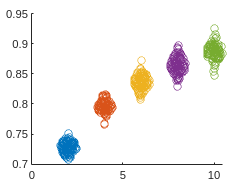

figure;
hold on
for i = 1:length(mean_correlations)
    x1 = ones(1,length(mean_correlations{i})) * i * 2;
    swarmchart(x1, mean_correlations{i})
end

hold off

for i = 1:length(mean_correlations)
    mean(mean_correlations{i},"omitnan")
end

ans = 0.7280

ans = 0.7962

ans = 0.8361

ans = 0.8644

ans = 0.8876

**(2.4)** K-means clustering computed on global correlation structure alone doesn't in general preserve spatial contiguity, a requirement of all good parcellation schemes. Think of, and describe, two ways in which you could modify this algorithm (either before, during, or after the main iteration loop) to ensure that it returns a spatially contiguous parcellation output.

The first way that I would fix this would be by adding a penalty term to k means clustering that would weak the correlation as nodes are assigned to non-contiguitous parcels on either side. This would be done after the calculation of the correlation step. You would subtract the dfifference of (current region - closer neighboor)/(number of regions). The reason you would subtract the closet neighbor is this way nodes that are borders would not be penalized i.e. you would subtract zero. Also, as correlations get closer and closer to thier neighbor the penalty would lessen. The division of the number of regions is to try and prevent the penalty term from being to large. Then after this step you would reassign regions to the closest node. You then repeat this until the algorithim converges. It is possible this wouldnt necessarily force everything to be spatially contigious; however, it seems like occasionally certain non contigious nodes might be very highly correlated at which point forcing them together seems detrimental.

 The second way to approach this and maybe the easiest way would be to just force a node to be assigned to the cluster that maximizes its correlation while also being spatially contigious. This step would happen during the assinging in the while loop of the k-means algorithim. So after assigning the algorithim would continue to run until it converges. This way you would hopefully get a more accurate result than if you just reassigned at the very end. 

#### Location of helper function: see (2.1) for details

function [K, mean_corr] = myKmeans(X, num_clusters) 
    % data dimensions;
    [n, t] = size(X);
    
    % 1. choose number of clusters
    c = num_clusters;
    
    % 2. make initial random partition
    K = randi(c, n, 1);
    
    % 3. iterate until convergence
    convergence = false;
    while ~convergence
        % old partition
        Kold = K;
        
        % 4. compute centroid for each cluster
        X_centroid = zeros(c, t);
        for u = 1:c
            X_centroid(u, :) = mean(X(K == u, :), 1);
        end
        
        % 5. compute correlation of each node to each centroid
        C = corr(X', X_centroid');
        
        % 6. assign each node to it's most strongly correlated cluster
        [~, K] = max(C, [], 2);
        mean_corr = [];
        for i = 1:size(C,2)
            winners = C(K == i, :);
            winners = winners(:,i);
            mean_corr = [mean_corr, winners'];
        end
        mean_corr = mean(mean_corr);
        % check convergence
        convergence = isequal(Kold, K);
        
        % print number of changes
    
        
        disp("fractional change: "+round(mean(Kold~=K), 4) + " | mean correlation: " + mean_corr); 
    end
end
